# vertical articulated arm robot

clear, clc, close all;

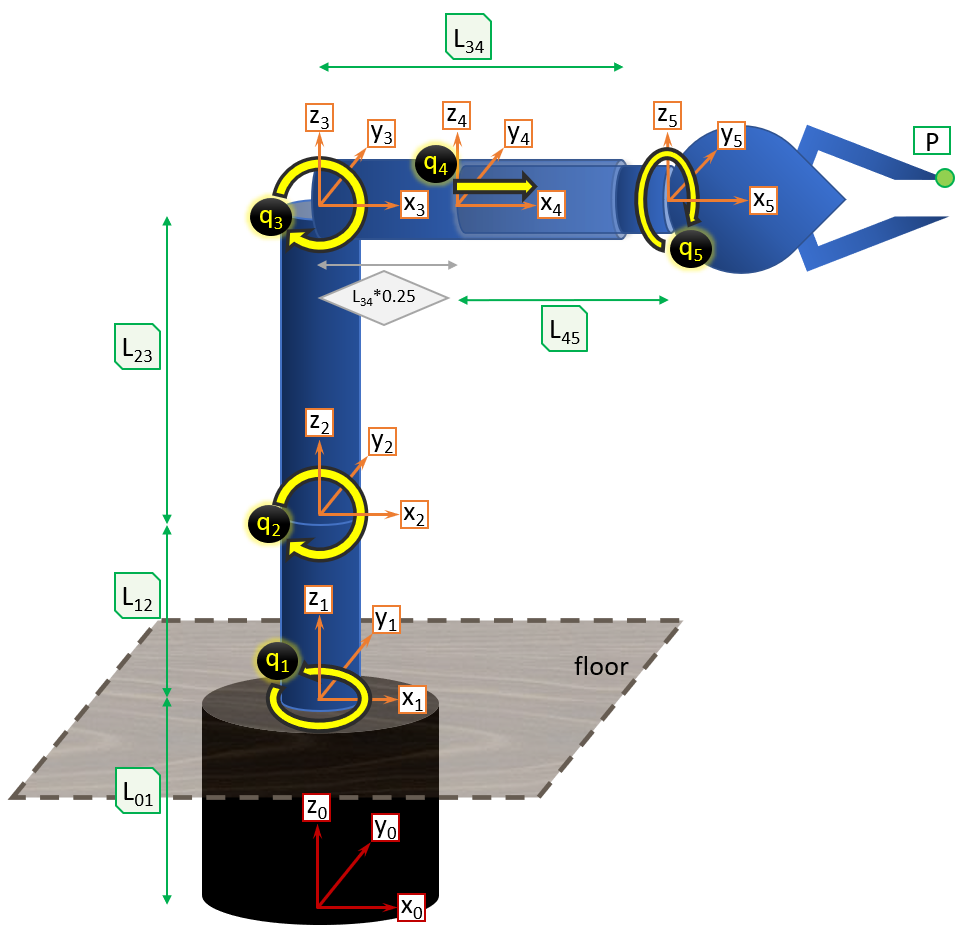

**Zero reference position: **

- Bodies 1 and 2 are orthogonal to the floor

- Bodies 3 to 5 are parallel to the floor

- All directions of the body reference frame axis are pointing into the same direction as the initial frame axis

- Body 4 is a hollow cylinder

- Body 1 to 3 are solid cylinders

- Body 5 is a globe

**Notes:**

- The robot arm consists of 5 bodies.

- ‘Body 0’ is the part of the robot that is installed in a solid base and prevents the robot from tipping over.

- The Tip P is a spot which is located in the $x_5/z_5$ plane

## 1. Kinematics

% DEF: time dependent generalised joint coordinates
syms q1(t) q2(t) q3(t) q4(t) q5(t)

% transformation matrices
T_10 = [cos(q1(t)) -sin(q1(t)) 0; sin(q1(t)) cos(q1(t)) 0; 0 0 1];
T_21 = [cos(q2(t)) 0 sin(q2(t)); 0 1 0; -sin(q2(t)) 0 cos(q2(t))];
T_32 = [cos(q3(t)) 0 sin(q3(t)); 0 1 0; -sin(q3(t)) 0 cos(q3(t))];
T_43 = eye(3);
T_54 = [1 0 0; 0 cos(q5(t)) -sin(q5(t)); 0 sin(q5(t)) cos(q5(t))];

% DEF: initial lengths of bodys
L_01=100; % [mm]
L_12=150; % [mm]
L_23=250; % [mm]
L_34=200; % [mm]
L_45=125; % [mm]

% DEF: position of joints with respect to inertial frame
syms r_0P_0   r_0J1_0   r_J1J2_0   r_J2J3_0   r_J3J4_0   r_J4J5_0   r_J5P_0

% initial positions in body reference frames
r_0J1_0  = [0;0;L_01]; % [mm]
r_J1J2_1 = [0;0;L_12]; % [mm]
r_J2J3_2 = [0;0;L_23]; % [mm]
r_J3J4_3 = [L_34*0.25+q4(t);0;0]; % [mm]
r_J4J5_4 = [L_45;0;0]; % [mm]
r_J5P_5  = [100;0;5]; % [mm]

% position of joints with respect to inertial frame
r_J1J2_0 = simplify(T_10 * r_J1J2_1);
r_J2J3_0 = simplify(T_10 * T_21 * r_J2J3_2);
r_J3J4_0 = simplify(T_10 * T_21 * T_32 * r_J3J4_3);
r_J4J5_0 = simplify(T_10 * T_21 * T_32 * T_43 * r_J4J5_4);
r_J5P_0  = simplify(T_10 * T_21 * T_32 * T_43 * T_54 * r_J5P_5);

% position of tip P with respect to inertial frame
r_0P_0 = simplify(r_0J1_0 + r_J1J2_0 + r_J2J3_0 + r_J3J4_0 + r_J4J5_0 + r_J5P_0);

###     **1.1 Plausibility check - Kinematics // Forward Kinematics**

Forward Kinematics:

`Input` = Werte der einzelnen q's

`Output` = Position des end effectors Tip


$$\left\lbrack \begin{array}{c}
\gamma_1 \\
\beta_2 \\
\beta_3 \\
l_4 \\
\alpha_5 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\textrm{rad}\\
\textrm{rad}\\
\textrm{rad}\\
\textrm{mm}\\
\textrm{rad}
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
q_1 \\
q_2 \\
q_3 \\
q_4 \\
q_5 
\end{array}\right\rbrack =q$$
    
$$q^{\textrm{Check1}} =\left\lbrack \begin{array}{c}
0\\
0\\
0\\
0\\
0
\end{array}\right\rbrack$$
    
$$q^{\textrm{Check2}} =\left\lbrack \begin{array}{c}
\frac{\pi }{2}\\
0\\
0\\
10\\
0
\end{array}\right\rbrack$$
    
$$q^{\textrm{Check3}} =\left\lbrack \begin{array}{c}
\frac{\pi }{2}\\
\frac{\pi }{2}\\
0\\
10\\
0
\end{array}\right\rbrack$$
    
$$q^{\textrm{Check4}} =\left\lbrack \begin{array}{c}
\frac{\pi }{2}\\
\frac{\pi }{2}\\
-\frac{\pi }{2}\\
10\\
0
\end{array}\right\rbrack$$
    
$$q^{\textrm{Check5}} =\left\lbrack \begin{array}{c}
\frac{\pi }{2}\\
\frac{\pi }{2}\\
-\frac{\pi }{2}\\
10\\
\frac{\pi }{2}
\end{array}\right\rbrack$$


Check_Kinematics = "Check5_KNMTX";
switch Check_Kinematics
    case "Check1_KNMTX";   check_r_Soll = [275; 0; 505];   Kuh = [0 0 0 0 0];
    case "Check2_KNMTX";   check_r_Soll = [0; 285; 505];   Kuh = [pi/2 0 0 10 0];
    case "Check3_KNMTX";   check_r_Soll = [0; 255; -35];   Kuh = [pi/2 pi/2 0 10 0];
    case "Check4_KNMTX";   check_r_Soll = [0; 535; 255];   Kuh = [pi/2 pi/2 -pi/2 10 0];
    case "Check5_KNMTX";   check_r_Soll = [5; 535; 250];   Kuh = [pi/2 pi/2 -pi/2 10 pi/2];
end


$$r_{\textrm{Soll}}^{\textrm{Check1}} =\left\lbrack \begin{array}{cc}
275 & \textrm{mm}\\
0 & \textrm{mm}\\
505 & \textrm{mm}
\end{array}\right\rbrack$$
    
$$r_{\textrm{Soll}}^{\textrm{Check2}} =\left\lbrack \begin{array}{cc}
0 & \textrm{mm}\\
285 & \textrm{mm}\\
505 & \textrm{mm}
\end{array}\right\rbrack$$
    
$$r_{\textrm{Soll}}^{\textrm{Check3}} =\left\lbrack \begin{array}{cc}
0 & \textrm{mm}\\
255 & \textrm{mm}\\
-35 & \textrm{mm}
\end{array}\right\rbrack$$
    
$$r_{\textrm{Soll}}^{\textrm{Check4}} =\left\lbrack \begin{array}{cc}
0 & \textrm{mm}\\
535 & \textrm{mm}\\
255 & \textrm{mm}
\end{array}\right\rbrack$$
    
$$r_{\textrm{Soll}}^{\textrm{Check5}} =\left\lbrack \begin{array}{cc}
5 & \textrm{mm}\\
535 & \textrm{mm}\\
250 & \textrm{mm}
\end{array}\right\rbrack$$


check_r_Ist = subs( r_0P_0, ...
                   [q1(t) q2(t) q3(t) q4(t) q5(t)], ...
                    Kuh)

$$check\_r\_Ist = \left(\begin{array}{c} 5\\ 535\\ 250 \end{array}\right)$$

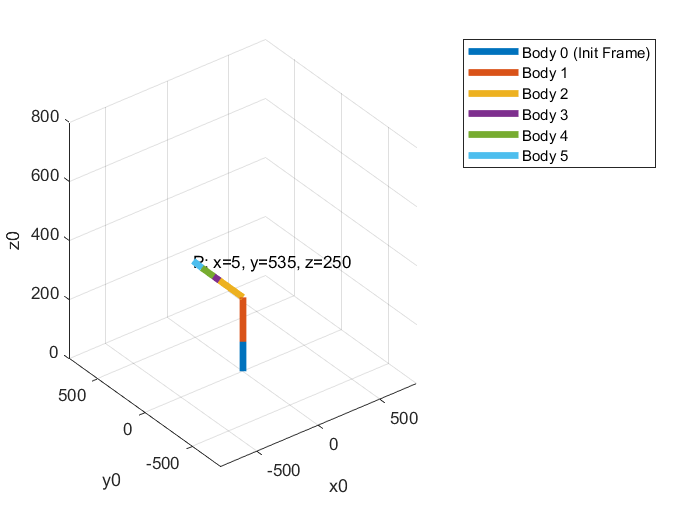

ans =   Figure (1: position of robots tip T) with properties:

      Number: 1
        Name: 'position of robots tip T'
       Color: [1 1 1]
    Position: [584 630 560 420]
       Units: 'pixels'

  Show all properties


% plot chain3dplot
P1_in0 = r_0J1_0;
P2_in0 = P1_in0 + r_J1J2_0;
P3_in0 = P2_in0 + r_J2J3_0;
P4_in0 = P3_in0 + r_J3J4_0;
P5_in0 = P4_in0 + r_J4J5_0;
P6_in0 = P5_in0 + r_J5P_0;
P_matrix = subs([zeros(3,1), P1_in0, P2_in0, P3_in0, P4_in0, P5_in0, P6_in0], ...
                [q1(t) q2(t) q3(t) q4(t) q5(t)], ...
                 Kuh);
chain3dplot(P_matrix)

## 2. Kinetic Energy

###     2.1 Translatory kinetic energy

% body masses [kg]
m1 = 1;
m2 = 2;
m3 = 0.5;
m4 = 1;
m5 = 1.5;

####         a) Translatory velocities

% positions of centre of masses in body reference frames
r_J1cm1_1 = [0;0;L_12/2];
r_J2cm2_2 = [0;0;L_23/2];
r_J3cm3_3 = [L_34/2;0;0];
r_J4cm4_4 = [L_45/2;0;0];
r_J5cm5_5 = [1;0;0];

% positions of centre of masses in zero reference frame 
r_0cm1_0 = simplify(r_0J1_0 + T_10 * r_J1cm1_1);
r_0cm2_0 = simplify(r_0J1_0 + r_J1J2_0 + T_10 * T_21 * r_J2cm2_2);
r_0cm3_0 = simplify(r_0J1_0 + r_J1J2_0 + r_J2J3_0 + T_10 * T_21 * T_32 * r_J3cm3_3);
r_0cm4_0 = simplify(r_0J1_0 + r_J1J2_0 + r_J2J3_0 + r_J3J4_0 + T_10 * T_21 * T_32 * T_43 * r_J4cm4_4);
r_0cm5_0 = simplify(r_0J1_0 + r_J1J2_0 + r_J2J3_0 + r_J3J4_0 + r_J4J5_0 + T_10 * T_21 * T_32 * T_43 * T_54 * r_J5cm5_5);

% velocities of centre of masses in zero reference frame
v_0cm1_0 = simplify(diff(r_0cm1_0, t));
v_0cm2_0 = simplify(diff(r_0cm2_0, t));
v_0cm3_0 = simplify(diff(r_0cm3_0, t));
v_0cm4_0 = simplify(diff(r_0cm4_0, t));
v_0cm5_0 = simplify(diff(r_0cm5_0, t));

####         b) Total translatory energy

% translatory kinetic energy of bodys
E1_trns = simplify(1/2 * m1 * v_0cm1_0.' * v_0cm1_0);
E2_trns = simplify(1/2 * m2 * v_0cm2_0.' * v_0cm2_0);
E3_trns = simplify(1/2 * m3 * v_0cm3_0.' * v_0cm3_0);
E4_trns = simplify(1/2 * m4 * v_0cm4_0.' * v_0cm4_0);
E5_trns = simplify(1/2 * m5 * v_0cm5_0.' * v_0cm5_0);

% total translatory kinetic energy
E_trns = simplify(E1_trns + E2_trns + E3_trns + E4_trns + E5_trns);

###     2.2 Rotary kinetic energy

####         a) Moments of inertia

% radiuses of the bodies [mm]
r1=10;   r2=10;   r3=10;   r4= 9;   r5=10;

% moments of inertia with respect to the reference frame of each body
I1_1 = diag([1/4*m1*r1^2+1/12*m1*L_12^2,   1/4*m1*r1^2+1/12*m1*L_12^2,   0.5*m1*r1^2]);  % Voll-zylinder
I2_2 = diag([1/4*m2*r2^2+1/12*m2*L_23^2,   1/4*m2*r2^2+1/12*m2*L_23^2,   0.5*m2*r2^2]);  % Voll-zylinder
I3_3 = diag([0.5*m3*(r3^2+r4^2),   1/4*m3*(r3^2+r4^2)+1/12*m3*L_34^2,    1/4*m3*(r3^2+r4^2)+1/12*m3*L_34^2]);  % Hohl-zylinder
I4_4 = diag([0.5*m4*r4^2,   1/4*m4*r4^2+1/12*m4*L_45^2,   1/4*m4*r4^2+1/12*m4*L_45^2]);  % Voll-zylinder
I5_5 = (2/5*m5*r5^2)*eye(3);   % Kugel

% moments of inertia with respect to zero reference frame
I1_0 =  T_10 * I1_1 * T_10.';
I2_0 = (T_10 * T_21 ) * I2_2 * (T_10 * T_21).';
I3_0 = (T_10 * T_21 * T_32 ) * I3_3 * (T_10 * T_21 * T_32).';
I4_0 = (T_10 * T_21 * T_32 * T_43 ) * I4_4 * (T_10 * T_21 * T_32 * T_43).';
I5_0 = (T_10 * T_21 * T_32 * T_43 * T_54 ) * I5_5 * (T_10 * T_21 * T_32 * T_43 * T_54).';

####         b) Rotary velocities

% DEF: time dependent generalised joint velocities
syms dq1(t) dq2(t) dq3(t) dq4(t) dq5(t)

% time dependent joint velocities
dq1 = diff(q1(t), t);
dq2 = diff(q2(t), t);
dq3 = diff(q3(t), t);
dq4 = diff(q4(t), t);
dq5 = diff(q5(t), t);

w_J10_1  = [0; 0; dq1];
w_J2J1_2 = [0; dq2; 0];
w_J3J2_3 = [0; dq3; 0];
w_J4J3_4 = [0;   0; 0];
w_J5J4_5 = [dq5; 0; 0];

w_J10_0  = simplify(T_10* w_J10_1);
w_J2J1_0 = simplify(T_10* T_21* w_J2J1_2);
w_J3J2_0 = simplify(T_10* T_21* T_32* w_J3J2_3);
w_J4J3_0 = simplify(T_10* T_21* T_32* T_43* w_J4J3_4);
w_J5J4_0 = simplify(T_10* T_21* T_32* T_43* T_54* w_J5J4_5);

w_J20_0 = simplify(w_J10_0 + w_J2J1_0 );
w_J30_0 = simplify(w_J10_0 + w_J2J1_0 + w_J3J2_0 );
w_J40_0 = simplify(w_J10_0 + w_J2J1_0 + w_J3J2_0 + w_J4J3_0 );
w_J50_0 = simplify(w_J10_0 + w_J2J1_0 + w_J3J2_0 + w_J4J3_0 + w_J5J4_0);

####         c) Total rotatory energy

% rotary kinetic energy of each body
E1_rot = simplify(1/2 * w_J10_0.' * I1_0 * w_J10_0);
E2_rot = simplify(1/2 * w_J20_0.' * I2_0 * w_J20_0);
E3_rot = simplify(1/2 * w_J30_0.' * I3_0 * w_J30_0);
E4_rot = simplify(1/2 * w_J40_0.' * I4_0 * w_J40_0);
E5_rot = simplify(1/2 * w_J50_0.' * I5_0 * w_J50_0);

% total rotary kinetic energy
E_rot = simplify(E1_rot + E2_rot + E3_rot + E4_rot + E5_rot);

###     2.3 Total kinetic energy

% Total kinetic energy
E_kin = simplify(E_trns + E_rot);

## 3. Potential energy

% DEF: Gravitation
syms grav_x grav_y grav_z
grav = [grav_x; grav_y; grav_z];

% potential energy of each body
E1_pot = simplify(m1 * r_0cm1_0.' * -grav);
E2_pot = simplify(m2 * r_0cm2_0.' * -grav);
E3_pot = simplify(m3 * r_0cm3_0.' * -grav);
E4_pot = simplify(m4 * r_0cm4_0.' * -grav);
E5_pot = simplify(m5 * r_0cm5_0.' * -grav);

% total potential energy
E_pot = simplify(E1_pot + E2_pot + E3_pot + E4_pot + E5_pot);

## 4. Virtual work

% DEF: Hold work resulting in external forces
syms M_hold_z1   M_hold_y2   M_hold_y3   F_hold_x4   M_hold_x5

% External forces in body reference frames in dependence of generelised joint coordinates
F_J1_1 = [0         ;0         ;M_hold_z1 ];
F_J2_2 = [0         ;M_hold_y2 ;0         ];
F_J3_3 = [0         ;M_hold_y3 ;0         ];
F_J4_4 = [F_hold_x4 ;0         ;0         ];
F_J5_5 = [M_hold_x5 ;0         ;0         ];

% External forces in zero reference frame coordinates
F_J1_0 = F_J1_1;
F_J2_0 = T_10 * F_J2_2;
F_J3_0 = T_10 * T_21 * F_J3_3;
F_J4_0 = T_10 * T_21 * T_32 * F_J4_4;
F_J5_0 = T_10 * T_21 * T_32 * T_43 * F_J5_5;

% actio-reactio velocities in each joint
v_J1_0r = [0; 0; 0];    w_J0_0 = v_J1_0r;
v_J1_0a = w_J10_0;

v_J2_0r = w_J10_0;
v_J2_0a = w_J0_0 + w_J20_0;

v_J3_0r = w_J20_0 + w_J0_0;
v_J3_0a = w_J30_0;

v_J4_0r = diff(r_0J1_0 + r_J1J2_0 + r_J2J3_0, t);
v_J4_0a = diff(r_0J1_0 + r_J1J2_0 + r_J2J3_0 + r_J3J4_0, t);

v_J5_0r = w_J4J3_0 + w_J3J2_0 + w_J2J1_0 + w_J10_0 + w_J0_0;
v_J5_0a = w_J50_0;

syms vW1   vW2   vW3   vW4   vW5
syms vq1   vq2   vq3   vq4   vq5

% generalised virtual work
vW1 = simplify(...
 F_J1_0.' * diff(v_J1_0a, dq1) * vq1 - F_J1_0.' * diff(v_J1_0r, dq1) * vq1 + ...
 F_J2_0.' * diff(v_J2_0a, dq1) * vq1 - F_J2_0.' * diff(v_J2_0r, dq1) * vq1 + ...
 F_J3_0.' * diff(v_J3_0a, dq1) * vq1 - F_J3_0.' * diff(v_J3_0r, dq1) * vq1 + ...
 F_J4_0.' * diff(v_J4_0a, dq1) * vq1 - F_J4_0.' * diff(v_J4_0r, dq1) * vq1 + ...
 F_J5_0.' * diff(v_J5_0a, dq1) * vq1 - F_J5_0.' * diff(v_J5_0r, dq1) * vq1 );

vW2 = simplify(...
 F_J1_0.' * diff(v_J1_0a, dq2) * vq2 - F_J1_0.' * diff(v_J1_0r, dq2) * vq2 + ...
 F_J2_0.' * diff(v_J2_0a, dq2) * vq2 - F_J2_0.' * diff(v_J2_0r, dq2) * vq2 + ...
 F_J3_0.' * diff(v_J3_0a, dq2) * vq2 - F_J3_0.' * diff(v_J3_0r, dq2) * vq2 + ...
 F_J4_0.' * diff(v_J4_0a, dq2) * vq2 - F_J4_0.' * diff(v_J4_0r, dq2) * vq2 + ...
 F_J5_0.' * diff(v_J5_0a, dq2) * vq2 - F_J5_0.' * diff(v_J5_0r, dq2) * vq2 );

vW3 = simplify(...
 F_J1_0.' * diff(v_J1_0a, dq3) * vq3 - F_J1_0.' * diff(v_J1_0r, dq3) * vq3 + ...
 F_J2_0.' * diff(v_J2_0a, dq3) * vq3 - F_J2_0.' * diff(v_J2_0r, dq3) * vq3 + ...
 F_J3_0.' * diff(v_J3_0a, dq3) * vq3 - F_J3_0.' * diff(v_J3_0r, dq3) * vq3 + ...
 F_J4_0.' * diff(v_J4_0a, dq3) * vq3 - F_J4_0.' * diff(v_J4_0r, dq3) * vq3 + ...
 F_J5_0.' * diff(v_J5_0a, dq3) * vq3 - F_J5_0.' * diff(v_J5_0r, dq3) * vq3 );

vW4 = simplify(...
 F_J1_0.' * diff(v_J1_0a, dq4) * vq4 - F_J1_0.' * diff(v_J1_0r, dq4) * vq4 + ...
 F_J2_0.' * diff(v_J2_0a, dq4) * vq4 - F_J2_0.' * diff(v_J2_0r, dq4) * vq4 + ...
 F_J3_0.' * diff(v_J3_0a, dq4) * vq4 - F_J3_0.' * diff(v_J3_0r, dq4) * vq4 + ...
 F_J4_0.' * diff(v_J4_0a, dq4) * vq4 - F_J4_0.' * diff(v_J4_0r, dq4) * vq4 + ...
 F_J5_0.' * diff(v_J5_0a, dq4) * vq4 - F_J5_0.' * diff(v_J5_0r, dq4) * vq4 );

vW5 = simplify(...
 F_J1_0.' * diff(v_J1_0a, dq5) * vq5 - F_J1_0.' * diff(v_J1_0r, dq5) * vq5 + ...
 F_J2_0.' * diff(v_J2_0a, dq5) * vq5 - F_J2_0.' * diff(v_J2_0r, dq5) * vq5 + ...
 F_J3_0.' * diff(v_J3_0a, dq5) * vq5 - F_J3_0.' * diff(v_J3_0r, dq5) * vq5 + ...
 F_J4_0.' * diff(v_J4_0a, dq5) * vq5 - F_J4_0.' * diff(v_J4_0r, dq5) * vq5 + ...
 F_J5_0.' * diff(v_J5_0a, dq5) * vq5 - F_J5_0.' * diff(v_J5_0r, dq5) * vq5 );

% total virtual work
vW = vW1 + vW2 + vW3 + vW4 + vW5;

% generalised forces
Q1 = simplify(diff(vW, vq1));
Q2 = simplify(diff(vW, vq2));
Q3 = simplify(diff(vW, vq3));
Q4 = simplify(diff(vW, vq4));
Q5 = simplify(diff(vW, vq5));

###     4.2 Plausibility Check - total virtual Work

if Q1 == M_hold_z1   &&   Q2 == M_hold_y2   &&   Q3 == M_hold_y3   &&   Q4 == F_hold_x4   &&   Q5 == M_hold_x5
    fprintf('Total virtual work is zero !');
else
    fprintf('Something went wrong !');
end

Total virtual work is zero !

## 5. Equations of Motion - Lagrange's Equations

eom1 = Q1 == simplify(diff( diff(E_kin, dq1) ,t) - diff(E_kin, q1(t)) + diff(E_pot, q1(t)));
eom2 = Q2 == simplify(diff( diff(E_kin, dq2) ,t) - diff(E_kin, q2(t)) + diff(E_pot, q2(t)));
eom3 = Q3 == simplify(diff( diff(E_kin, dq3) ,t) - diff(E_kin, q3(t)) + diff(E_pot, q3(t)));
eom4 = Q4 == simplify(diff( diff(E_kin, dq4) ,t) - diff(E_kin, q4(t)) + diff(E_pot, q4(t)));
eom5 = Q5 == simplify(diff( diff(E_kin, dq5) ,t) - diff(E_kin, q5(t)) + diff(E_pot, q5(t)));

###     5.1 Plausibility Check - Equations of Motion

####         a) First type: Inverse Statics

Changing direction of gravity results in different external forces.

% DEF: time dependent generalized joint accelerations
syms ddq1(t) ddq2(t) ddq3(t) ddq4(t) ddq5(t)

% time dependent generalized joint accelerations
ddq1 = diff(dq1, t);
ddq2 = diff(dq2, t);
ddq3 = diff(dq3, t);
ddq4 = diff(dq4, t);
ddq5 = diff(dq5, t);

Check_EOM = "Check1_EOM";
switch Check_EOM
    case "Check1_EOM" % Arm in z0-direction, gravity in negative z0-direction
        eom_grav_x = 0; eom_grav_y = 0; eom_grav_z = -9.81;
        eom_q1 = 0;     eom_dq1 = 0;    eom_ddq1 = 0;
        eom_q2 = 0;     eom_dq2 = 0;    eom_ddq2 = 0;
        eom_q3 =-pi/2;  eom_dq3 = 0;    eom_ddq3 = 0;
        eom_q4 = 0;     eom_dq4 = 0;    eom_ddq4 = 0;
        eom_q5 = 0;     eom_dq5 = 0;    eom_ddq5 = 0;
        holdFM_Soll =[ M_hold_z1 == 0, ...
                       M_hold_y2 == 0, ...
                       M_hold_y3 == 0, ...
                       F_hold_x4 == -(m4+m5)*eom_grav_z, ...
                       M_hold_x5 == 0 ];

    case "Check2_EOM" % Arm in zero-reference-position, gravity in positive y0-direction
        eom_grav_x = 0; eom_grav_y = 9.81;  eom_grav_z = 0;
        eom_q1 = 0;     eom_dq1 = 0;        eom_ddq1 = 0;
        eom_q2 = 0;     eom_dq2 = 0;        eom_ddq2 = 0;
        eom_q3 = 0;     eom_dq3 = 0;        eom_ddq3 = 0;
        eom_q4 = 0;     eom_dq4 = 0;        eom_ddq4 = 0;
        eom_q5 = 0;     eom_dq5 = 0;        eom_ddq5 = 0;
        holdFM_Soll =[ M_hold_z1 == -( m3*r_J3cm3_3(1) ...
                                    +  m4*(L_34*0.25+eom_q4+r_J4cm4_4(1)) ...
                                    +  m5*(L_34*0.25+eom_q4+L_45+r_J5cm5_5(1)) ...
                                     )*eom_grav_y, ...
                       M_hold_y2 == 0, ...
                       M_hold_y3 == 0, ...
                       F_hold_x4 == 0, ...
                       M_hold_x5 == m5*r_J5cm5_5(3)*eom_grav_y ];

    case "Check3_EOM" % Arm in zero-reference-position, gravity in positive z0-direction
        eom_grav_x = 0; eom_grav_y = 0; eom_grav_z = 9.81;
        eom_q1 = 0;     eom_dq1 = 0;    eom_ddq1 = 0;
        eom_q2 = 0;     eom_dq2 = 0;    eom_ddq2 = 0;
        eom_q3 = 0;     eom_dq3 = 0;    eom_ddq3 = 0;
        eom_q4 = 0;     eom_dq4 = 0;    eom_ddq4 = 0;
        eom_q5 = 0;     eom_dq5 = 0;    eom_ddq5 = 0;
        holdFM_Soll =[ M_hold_z1 == 0, ...
                       M_hold_y2 ==  (m3*r_J3cm3_3(1) ...
                                    + m4*(L_34*0.25+eom_q4+r_J4cm4_4(1)) ...
                                    + m5*(L_34*0.25+eom_q4+L_45+r_J5cm5_5(1)) ...
                                     )*eom_grav_z, ...
                       M_hold_y3 ==  (m3*r_J3cm3_3(1) ...
                                    + m4*(L_34*0.25+eom_q4+r_J4cm4_4(1)) ...
                                    + m5*(L_34*0.25+eom_q4+L_45+r_J5cm5_5(1)) ...
                                     )*eom_grav_z, ...
                       F_hold_x4 == 0, ...
                       M_hold_x5 == 0 ];

    case "Check4_EOM" % Arm in zero-reference-position, gravity in negative x0-direction
        eom_grav_x = -9.81; eom_grav_y = 0; eom_grav_z = 0;
        eom_q1 = 0;         eom_dq1 = 0;    eom_ddq1 = 0;
        eom_q2 = 0;         eom_dq2 = 0;    eom_ddq2 = 0;
        eom_q3 = 0;         eom_dq3 = 0;    eom_ddq3 = 0;
        eom_q4 = 0;         eom_dq4 = 0;    eom_ddq4 = 0;
        eom_q5 = 0;         eom_dq5 = 0;    eom_ddq5 = 0;
        holdFM_Soll =[ M_hold_z1 == 0, ...
                       M_hold_y2 == -((m3+m4+m5)*L_23 ...
                                    +  m2*r_J2cm2_2(3)...
                                     )*eom_grav_x, ...
                       M_hold_y3 == 0, ...
                       F_hold_x4 == -(m4+m5)*eom_grav_x, ...
                       M_hold_x5 == 0 ];
    
end % switch Check_EOM

holdFM_Ist = vpa(subs([eom1, eom2, eom3, eom4, eom5], ...
            [q1(t)   diff(q1(t), t)    diff(diff(q1(t), t), t) ...
             q2(t)   diff(q2(t), t)    diff(diff(q2(t), t), t) ...
             q3(t)   diff(q3(t), t)    diff(diff(q3(t), t), t) ...
             q4(t)   diff(q4(t), t)    diff(diff(q4(t), t), t) ...
             q5(t)   diff(q5(t), t)    diff(diff(q5(t), t), t) ...
             grav_x   grav_y   grav_z], ...
            [eom_q1  eom_dq1           eom_ddq1 ...
             eom_q2  eom_dq2           eom_ddq2 ...
             eom_q3  eom_dq3           eom_ddq3 ...
             eom_q4  eom_dq4           eom_ddq4 ...
             eom_q5  eom_dq5           eom_ddq5 ...
             eom_grav_x   eom_grav_y   eom_grav_z]), 5)

$$holdFM\_Ist = \left(\begin{array}{ccccc} M_{\mathrm{hold},\mathrm{z1}}=0.0 & M_{\mathrm{hold},\mathrm{y2}}=0.0 & M_{\mathrm{hold},\mathrm{y3}}=0.0 & F_{\mathrm{hold},\mathrm{x4}}=24.525 & M_{\mathrm{hold},\mathrm{x5}}=0.0 \end{array}\right)$$


holdFM_Soll = vpa(holdFM_Soll, 5)

$$holdFM\_Soll = \left(\begin{array}{ccccc} M_{\mathrm{hold},\mathrm{z1}}=0.0 & M_{\mathrm{hold},\mathrm{y2}}=0.0 & M_{\mathrm{hold},\mathrm{y3}}=0.0 & F_{\mathrm{hold},\mathrm{x4}}=24.525 & M_{\mathrm{hold},\mathrm{x5}}=0.0 \end{array}\right)$$

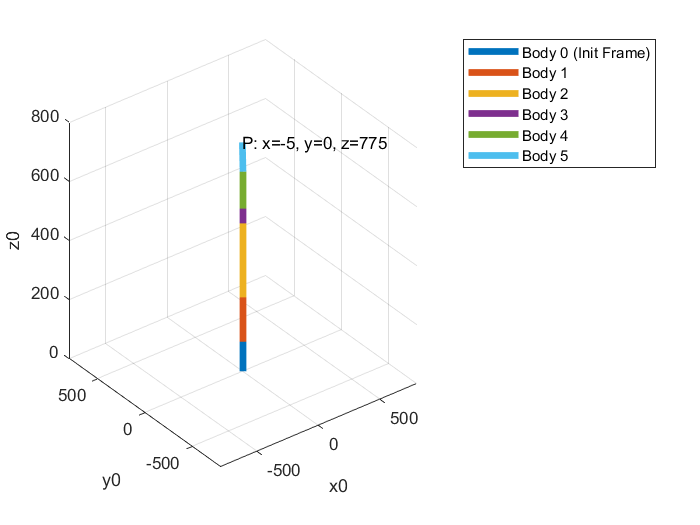

ans =   Figure (2: position of robots tip T) with properties:

      Number: 2
        Name: 'position of robots tip T'
       Color: [1 1 1]
    Position: [584 630 560 420]
       Units: 'pixels'

  Show all properties



P_matrix = subs([zeros(3,1), P1_in0, P2_in0, P3_in0, P4_in0, P5_in0, P6_in0], ...
                [q1(t) q2(t) q3(t) q4(t) q5(t)], ...
                [eom_q1 eom_q2 eom_q3 eom_q4 eom_q5]);
chain3dplot(P_matrix)

####         b) Second Type: Inverse Dynamics

% if Enable_ID_Check
syms q_1(t) q_2(t) q_3(t) q_4(t) q_5(t)
syms v_1(t) v_2(t) v_3(t) v_4(t) v_5(t) 
syms a_1    a_2    a_3    a_4    a_5

% generalized coordinates and velocities as integrals of the joint accelerations
v_1 = int(a_1, t);   q_1 = int(int(a_1, t), t);
v_2 = int(a_2, t);   q_2 = int(int(a_2, t), t);
v_3 = int(a_3, t);   q_3 = int(int(a_3, t), t);   
v_4 = int(a_4, t);   q_4 = int(int(a_4, t), t);
v_5 = int(a_5, t);   q_5 = int(int(a_5, t), t);

Check_ID = "Check2_ID";
switch Check_ID
    case "Check1_ID" % Constant acceleration around z1-axis in fixed zero-reference-position
        eom_a_1 = 10; eom_a_2 = 0; eom_a_3 = 0; eom_a_4 = 0; eom_a_5 = 0;
    case "Check2_ID" % Constant acceleration around y3-axis
        eom_a_1 = 0; eom_a_2 = 0; eom_a_3 = 10; eom_a_4 = 0; eom_a_5 = 0;
end % switch Check_ID

eom_a = [eom_a_1   eom_a_2   eom_a_3   eom_a_4   eom_a_5];
eom_v = vpa(subs([v_1, v_2, v_3, v_4, v_5], ...
                 [a_1     a_2     a_3     a_4     a_5], ...
                 [eom_a_1 eom_a_2 eom_a_3 eom_a_4 eom_a_5]), 3);
eom_q = vpa(subs([q_1,  q_2,  q_3,  q_4,  q_5], ...
                 [a_1     a_2     a_3     a_4     a_5], ...
                 [eom_a_1 eom_a_2 eom_a_3 eom_a_4 eom_a_5]), 3);

% time vector for simulation
t_ID = [0 : 0.001*pi : 2*pi];

Trajectory of the generalized coordinates and their time derivatives

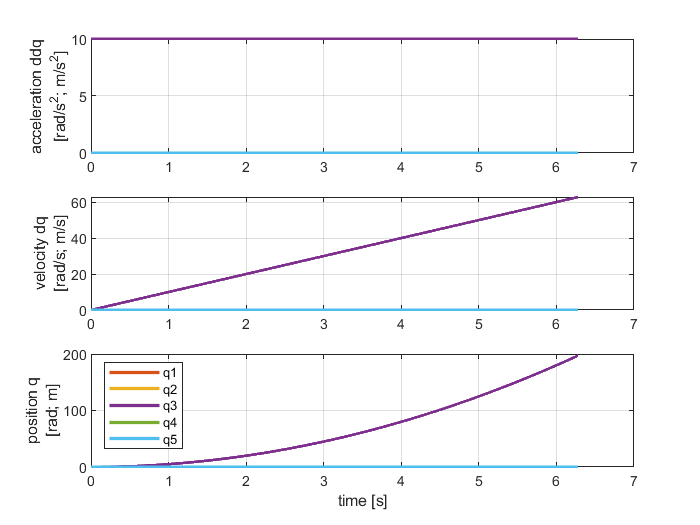

eom_a_ID = eom_a .* ones(length(t_ID), 5);
eom_v_ID = subs(eom_v.', t, t_ID).';
eom_q_ID = subs(eom_q.', t, t_ID).';

subplot(3,1,1), plot(t_ID, eom_a_ID(:,1), 'Color', [0.8500,0.3250,0.0980], 'LineWidth',2); hold on;
                plot(t_ID, eom_a_ID(:,2), 'Color', [0.9290,0.6940,0.1250], 'LineWidth',2);
                plot(t_ID, eom_a_ID(:,3), 'Color', [0.4940,0.1840,0.5560], 'LineWidth',2);
                plot(t_ID, eom_a_ID(:,4), 'Color', [0.4660,0.6740,0.1880], 'LineWidth',2);
                plot(t_ID, eom_a_ID(:,5), 'Color', [0.3010,0.7450,0.9330], 'LineWidth',2); hold off;
    ylabel({'acceleration ddq' ; '[rad/s^2; m/s^2]'}); grid;
subplot(3,1,2), plot(t_ID, eom_v_ID(:,1), 'Color', [0.8500,0.3250,0.0980], 'LineWidth',2); hold on;
                plot(t_ID, eom_v_ID(:,2), 'Color', [0.9290,0.6940,0.1250], 'LineWidth',2);
                plot(t_ID, eom_v_ID(:,3), 'Color', [0.4940,0.1840,0.5560], 'LineWidth',2);
                plot(t_ID, eom_v_ID(:,4), 'Color', [0.4660,0.6740,0.1880], 'LineWidth',2);
                plot(t_ID, eom_v_ID(:,5), 'Color', [0.3010,0.7450,0.9330], 'LineWidth',2); hold off;
    ylabel({'velocity dq' ; '[rad/s; m/s]'}); grid;
subplot(3,1,3), plot(t_ID, eom_q_ID(:,1), 'Color', [0.8500,0.3250,0.0980], 'LineWidth',2); hold on;
                plot(t_ID, eom_q_ID(:,2), 'Color', [0.9290,0.6940,0.1250], 'LineWidth',2);
                plot(t_ID, eom_q_ID(:,3), 'Color', [0.4940,0.1840,0.5560], 'LineWidth',2);
                plot(t_ID, eom_q_ID(:,4), 'Color', [0.4660,0.6740,0.1880], 'LineWidth',2);
                plot(t_ID, eom_q_ID(:,5), 'Color', [0.3010,0.7450,0.9330], 'LineWidth',2); hold off;
    ylabel({'position q' ; '[rad; m]'}); grid;
    xlabel('time [s]'); legend('q1', 'q2', 'q3', 'q4', 'q5', 'Location', 'northwest');

Trajectory of robots tip position P in zero-reference-frame

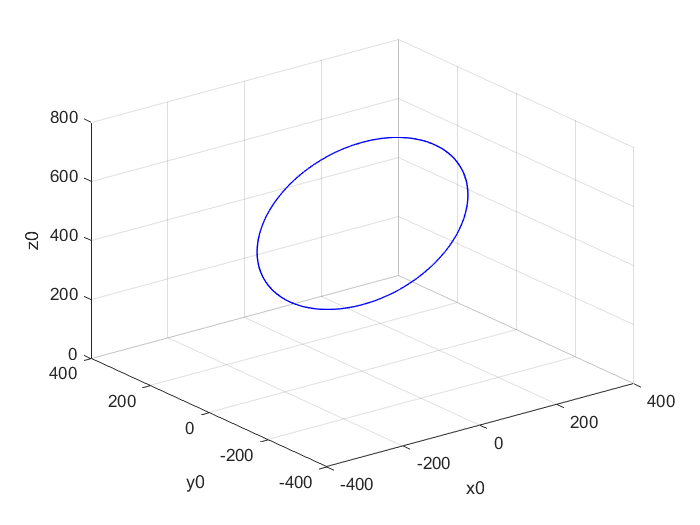

spacecurve_P = simplify(subs( r_0P_0, ...
                             [q1(t) q2(t) q3(t) q4(t) q5(t)], ...
                              eom_q));
spacecurve_P_ID = simplify(subs(spacecurve_P, t, t_ID).');

subplot(1,1,1), plot3(spacecurve_P_ID(:,1), spacecurve_P_ID(:,2), spacecurve_P_ID(:,3), 'b');
xlabel('x0'); ylabel('y0'); zlabel('z0');
xlim([-400 400]); ylim([-400 400]); zlim([0 800]); axis on; grid on;

Resulting joint forces and torques for inverse dynamics check

eom1_ID = simplify(diff( diff(E_kin, dq1) ,t) - diff(E_kin, q1(t)) + diff(E_pot, q1(t)));
eom2_ID = simplify(diff( diff(E_kin, dq2) ,t) - diff(E_kin, q2(t)) + diff(E_pot, q2(t)));
eom3_ID = simplify(diff( diff(E_kin, dq3) ,t) - diff(E_kin, q3(t)) + diff(E_pot, q3(t)));
eom4_ID = simplify(diff( diff(E_kin, dq4) ,t) - diff(E_kin, q4(t)) + diff(E_pot, q4(t)));
eom5_ID = simplify(diff( diff(E_kin, dq5) ,t) - diff(E_kin, q5(t)) + diff(E_pot, q5(t)));

jointFM_Ist = vpa(subs([eom1_ID, eom2_ID, eom3_ID, eom4_ID, eom5_ID], ...
            [q1(t)     diff(q1(t), t)   diff(diff(q1(t), t), t) ...
             q2(t)     diff(q2(t), t)   diff(diff(q2(t), t), t) ...
             q3(t)     diff(q3(t), t)   diff(diff(q3(t), t), t) ...
             q4(t)     diff(q4(t), t)   diff(diff(q4(t), t), t) ...
             q5(t)     diff(q5(t), t)   diff(diff(q5(t), t), t) ...
             grav_x    grav_y           grav_z], ...
            [eom_q(1)  eom_v(1)         eom_a(1) ...
             eom_q(2)  eom_v(2)         eom_a(2) ...
             eom_q(3)  eom_v(3)         eom_a(3) ...
             eom_q(4)  eom_v(4)         eom_a(4) ...
             eom_q(5)  eom_v(5)         eom_a(5) ...
             0         0                0]), 5)

$$jointFM\_Ist = \left(\begin{array}{ccccc} 0 & 671920.0-1.0662e+7\,t^{2}\,\cos\left(5.0\,t^{2}\right)-1.0662e+6\,\sin\left(5.0\,t^{2}\right) & 671920.0 & -37650.0\,t^{2} & 0 \end{array}\right)$$

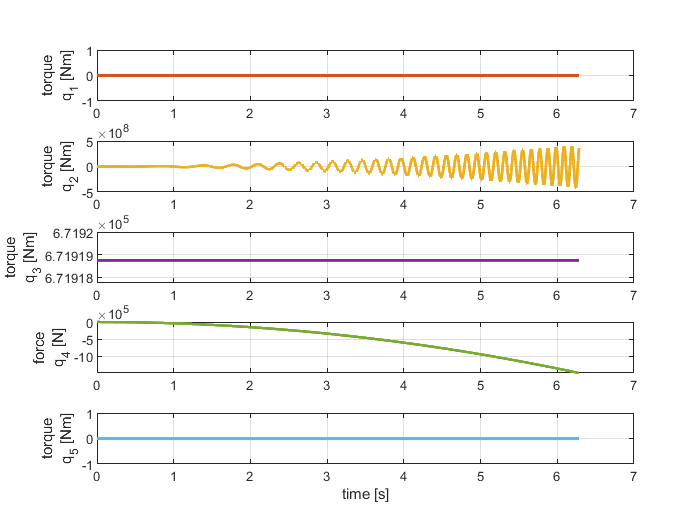

jointFM_Ist_ID = simplify(subs(jointFM_Ist.', t, t_ID).');

subplot(5,1,1), plot(t_ID, jointFM_Ist_ID(:,1), 'Color', [0.8500,0.3250,0.0980], 'LineWidth',2)
    ylabel({'torque' ; 'q_1 [Nm]'}), grid,
subplot(5,1,2), plot(t_ID, jointFM_Ist_ID(:,2), 'Color', [0.9290,0.6940,0.1250], 'LineWidth',2)
    ylabel({'torque' ; 'q_2 [Nm]'}), grid,
subplot(5,1,3), plot(t_ID, jointFM_Ist_ID(:,3), 'Color', [0.4940,0.1840,0.5560], 'LineWidth',2)
    ylabel({'torque' ; 'q_3 [Nm]'}), grid,
subplot(5,1,4), plot(t_ID, jointFM_Ist_ID(:,4), 'Color', [0.4660,0.6740,0.1880], 'LineWidth',2)
    ylabel({'force' ; 'q_4 [N]'}), grid,
subplot(5,1,5), plot(t_ID, jointFM_Ist_ID(:,5), 'Color', [0.3010,0.7450,0.9330], 'LineWidth',2)
    ylabel({'torque' ; 'q_5 [Nm]'}), grid, xlabel('time [s]');

## 6. Simulation

Check_SIM = "Check4_SIM";
switch Check_SIM

**Check 1:**

`Direction of gravity    `$\textrm{grav}=\left\lbrack \begin{array}{c}
0\\
0\\
+9\ldotp 81
\end{array}\right\rbrack$`;    Initial position    `$q_0 =\left\lbrack \begin{array}{c}
0\\
0\\
0\\
0\\
0
\end{array}\right\rbrack$`;    Initial velocity    `$\frac{d}{\mathrm{d}t}q_0 =\left\lbrack \begin{array}{c}
0\\
0\\
0\\
0\\
0
\end{array}\right\rbrack$`;    Max. deflection    `$q_{\max } =\left\lbrack \begin{array}{c}
-\infty <q_1 <\infty \;\\
-\infty <q_2 <\infty \;\;\\
-\infty \;<q_3 <\infty \;\\
-\infty <q_4 <\infty \\
-\infty <q_5 <\infty \;
\end{array}\right\rbrack$

    case "Check1_SIM" 
%            |        tN        |
        tN = 60*5;

%                      |      grav_x      |,|      grav_y      |,|      grav_z      |
        sub_grav_FD = [0,0,9.81].';

%             |        q1        |,|        q2        |,|        q3        |,|        q4        |,|        q5        |
%             |       dq1        |,|       dq2        |,|       dq3        |,|       dq4        |,|       dq5        |
        y0 = [0,0,0,0,0,...
              0,0,0,0,0];

      Damp = [0;0;0;0;0];

**Check 2:**

`Direction of gravity    `$\textrm{grav}=\left\lbrack \begin{array}{c}
0\\
0\\
+9\ldotp 81
\end{array}\right\rbrack$`;    Initial position    `$q_0 =\left\lbrack \begin{array}{c}
0\\
0\\
0\\
0\\
0
\end{array}\right\rbrack$`;    Initial velocity    `$\frac{d}{\mathrm{d}t}q_0 =\left\lbrack \begin{array}{c}
0\\
0\\
0\\
0\\
0
\end{array}\right\rbrack$`;    Max. deflection    `$q_{\max } =\left\lbrack \begin{array}{c}
-\infty <q_1 <\infty \;\\
-\infty <q_2 <\infty \;\;\\
-\infty \;<q_3 <\infty \;\\
-\infty <q_4 <\infty \\
-\infty <q_5 <\infty \;
\end{array}\right\rbrack$

    case "Check2_SIM"
%            |        tN        |
        tN = 60*5;

%                      |      grav_x      |,|      grav_y      |,|      grav_z      |
        sub_grav_FD = [0,0,9.81].';

%             |        q1        |,|        q2        |,|        q3        |,|        q4        |,|        q5        |
%             |       dq1        |,|       dq2        |,|       dq3        |,|       dq4        |,|       dq5        |
        y0 = [0,0,0,0,0,...
              0,0,0,0,0];

      Damp = [10000;10000;10000;10000;10000];

**Check 3:**

`Direction of gravity    `$\textrm{grav}=\left\lbrack \begin{array}{c}
-9\ldotp 81\\
0\\
0
\end{array}\right\rbrack$`;    Initial position    `$q_0 =\left\lbrack \begin{array}{c}
0\\
\frac{\pi \;}{2}\\
-\frac{\pi }{2}\\
50\\
0
\end{array}\right\rbrack$`;    Initial velocity    `$\frac{d}{\mathrm{d}t}q_0 =\left\lbrack \begin{array}{c}
0\\
0\\
0\\
0\\
0
\end{array}\right\rbrack$`;    Max. deflection    `$q_{\max } =\left\lbrack \begin{array}{c}
-\infty <q_1 <\infty \;\\
-\infty <q_2 <\infty \;\;\\
-\infty \;<q_3 <\infty \;\\
0<q_4 <150\\
-\infty <q_5 <\infty \;
\end{array}\right\rbrack$

    case "Check3_SIM" 
%            |        tN        |
        tN = 60*20;

%                      |      grav_x      |,|      grav_y      |,|      grav_z      |
        sub_grav_FD = [-9.81,0,0].';

%             |        q1        |,|        q2        |,|        q3        |,|        q4        |,|        q5        |
%             |       dq1        |,|       dq2        |,|       dq3        |,|       dq4        |,|       dq5        |
        y0 = [0,pi/2,-pi/2,50,0,...
              0,0,0,0,0];

      Damp = [1000;1000;1000;1;1000];

**Check 4:**

`Direction of gravity    `$\textrm{grav}=\left\lbrack \begin{array}{c}
9\ldotp 81\\
0\\
0
\end{array}\right\rbrack$`;    Initial position    `$q_0 =\left\lbrack \begin{array}{c}
0\\
\frac{\pi \;}{2}\\
-\frac{\pi }{2}\\
50\\
0
\end{array}\right\rbrack$`;    Initial velocity    `$\frac{d}{\mathrm{d}t}q_0 =\left\lbrack \begin{array}{c}
0\\
0\\
0\\
0\\
0
\end{array}\right\rbrack$`;    Max. deflection    `$q_{\max } =\left\lbrack \begin{array}{c}
-\infty <q_1 <\infty \;\\
-\infty <q_2 <\infty \;\;\\
-\infty \;<q_3 <\infty \;\\
0<q_4 <150\\
-\infty <q_5 <\infty \;
\end{array}\right\rbrack$

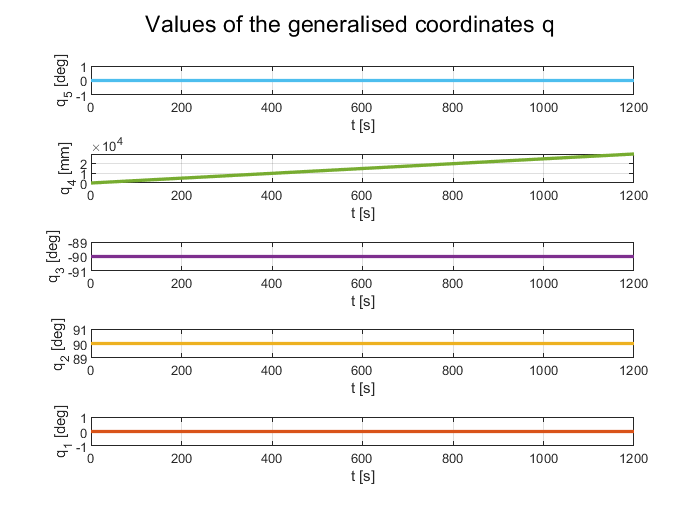

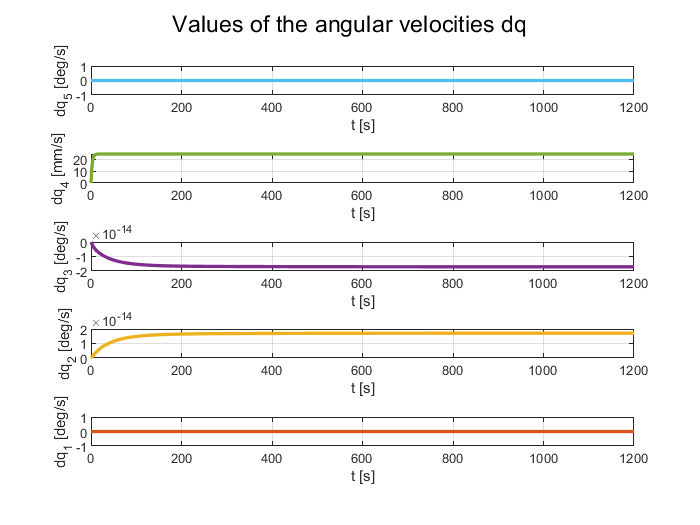

    case "Check4_SIM" 
%            |        tN        |
        tN = 60*20;

%                      |      grav_x      |,|      grav_y      |,|      grav_z      |
        sub_grav_FD = [9.81,0,0].';

%             |        q1        |,|        q2        |,|        q3        |,|        q4        |,|        q5        |
%             |       dq1        |,|       dq2        |,|       dq3        |,|       dq4        |,|       dq5        |
        y0 = [0,pi/2,-pi/2,50,0,...
              0,0,0,0,0];

      Damp = [1000;1000;1000;1;1000];
end

% equations of motion with optional damping
eom1 = Q1 == simplify(diff( diff(E_kin, dq1) ,t) - diff(E_kin, q1(t)) + diff(E_pot, q1(t))   +   Damp(1)*dq1 );
eom2 = Q2 == simplify(diff( diff(E_kin, dq2) ,t) - diff(E_kin, q2(t)) + diff(E_pot, q2(t))   +   Damp(2)*dq2 );
eom3 = Q3 == simplify(diff( diff(E_kin, dq3) ,t) - diff(E_kin, q3(t)) + diff(E_pot, q3(t))   +   Damp(3)*dq3 );
eom4 = Q4 == simplify(diff( diff(E_kin, dq4) ,t) - diff(E_kin, q4(t)) + diff(E_pot, q4(t))   +   Damp(4)*dq4 );
eom5 = Q5 == simplify(diff( diff(E_kin, dq5) ,t) - diff(E_kin, q5(t)) + diff(E_pot, q5(t))   +   Damp(5)*dq5 );

% create first order differential equations
Vec_eom = [ eom1, eom2, eom3, eom4, eom5 ];
Vec_q   = [ q1(t), q2(t), q3(t), q4(t), q5(t) ];
[newEqs, newVars] = reduceDifferentialOrder(Vec_eom, Vec_q);

% bring into form MassMatrix * Vec_ddq = all right hand side (RHS)
[MassMatrix, eom_RHS] = massMatrixForm(newEqs, newVars);

% DEF: valid MATLAB variable names for function handles
syms Ku1  Ku2  Ku3  Ku4  Ku5    dKu1  dKu2  dKu3  dKu4  dKu5

%        | q1 ............ q5    dq1 ........... dq5 |
% vecY = [ Y1  Y2  Y3  Y4  Y5    Y6  Y7  Y8  Y9  Y10 ].';
sub_KudKu_FD = [ Ku1  Ku2  Ku3  Ku4  Ku5    dKu1  dKu2  dKu3  dKu4  dKu5 ].';

Vec_Hold_FD = [ M_hold_z1   M_hold_y2   M_hold_y3   F_hold_x4   M_hold_x5 ].';
sub_Hold_FD = [ 0, 0, 0, 0, 0 ].';

MassMatrix  = subs([ MassMatrix ], ...
                   [ newVars; grav; Vec_Hold_FD ], ...
                   [ sub_KudKu_FD; sub_grav_FD; sub_Hold_FD ]);

eom_RHS  = subs([ eom_RHS ], ...
                [ newVars; grav; Vec_Hold_FD ], ...
                [ sub_KudKu_FD; sub_grav_FD; sub_Hold_FD ]);

% transform MassMatrix and eom_RHS into MATLAB-functions
MM_FD = matlabFunction(MassMatrix, 'vars', {t, sub_KudKu_FD});
FM_FD = matlabFunction(eom_RHS, 'vars', {t, sub_KudKu_FD});

y0 =          0    1.5708   -1.5708  149.0000         0         0    0.0000   -0.0000   22.6161         0


y0 =          0    1.5708   -1.5708  149.0000         0         0    0.0000   -0.0000   14.0989         0


y0 =          0    1.5708   -1.5708  149.0000         0         0    0.0000   -0.0000   10.6377         0


y0 =          0    1.5708   -1.5708  149.0000         0         0    0.0000    0.0000    8.9276         0


y0 =          0    1.5708   -1.5708  149.0000         0         0    0.0000    0.0000    8.0203         0


###     6.1 Inverse dynamics without joint limitations

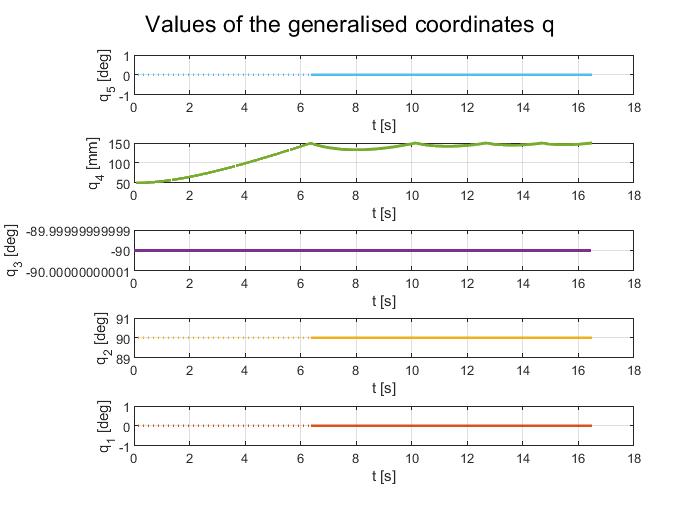

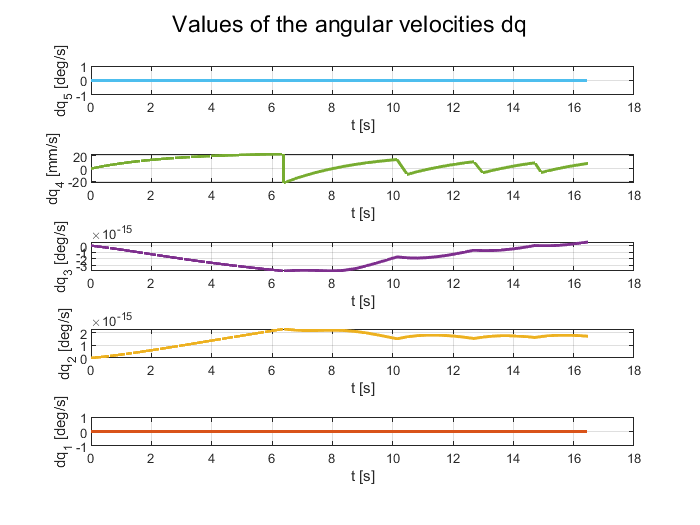

opts_woL = odeset('RelTol' ,0.001,...
                  'AbsTol' ,0.0001,...
                  'MaxStep',0.01,...
                  'Mass', MM_FD);

[t_woL, y_woL] = ode45(FM_FD, [0 tN] , y0, opts_woL);

y1_woL = y_woL(:, 1);  % q1
y2_woL = y_woL(:, 2);  % q2
y3_woL = y_woL(:, 3);  % q3
y4_woL = y_woL(:, 4);  % q4
y5_woL = y_woL(:, 5);  % q5

y6_woL = y_woL(:, 6);  % dq1
y7_woL = y_woL(:, 7);  % dq2
y8_woL = y_woL(:, 8);  % dq3
y9_woL = y_woL(:, 9);  % dq4
y10_woL= y_woL(:,10);  % dq5

ShowSimFig(t_woL,y1_woL,y2_woL,y3_woL,y4_woL,y5_woL,y6_woL,y7_woL,y8_woL,y9_woL,y10_woL);

###     6.2 Inverse dynamics with joint limitations

refine = 4;
opts_wL = odeset('RelTol' ,0.001,...
                 'AbsTol' ,0.0001,...
                 'MaxStep',0.01,...
                 'Refine', refine,...
                 'Mass', MM_FD,...
                 'Events', @jointlimits);

t0 = 0;         % starting time of simulation
tout = t0;      % tout and yout store the output time and state vector for each segment of simulations
yout = y0;      % a segment consists of all moves, terminated by a detected stop contact event of q4
teout = [];     % te: Time of the event (column vector)
yeout = [];     % ye: solution at the time of the event 
ieout = [];     % ie: Index of the triggered event


for i = 1:5     % loop to conduct up to 5 bounces
   % solve the ordinary differential equation until the terminal event
   [t_wL, y_wL, te, ye, ie] = ode45(FM_FD, [t0 tN] , y0, opts_wL);

   nt = length(t_wL);
   tout  = [tout; t_wL(2:nt)];   % with each segment of simulation, the output time and state are appended to ever-growing tout and yout vectors
   yout  = [yout; y_wL(2:nt,:)];

   teout = [teout; te];          % events at t0 are never reported
   yeout = [yeout; ye];
   ieout = [ieout; ie];
   
   y0 = y_wL(nt,:);              % set the new initial conditions

   if y_wL(nt,4) >= 150
        y0(4) = 149,99;          % after bounce, initial position q4_0 is 150 for the next flight phase
   elseif y_wL(nt,4) <= 0 
        y0(4) = 0.001;           % after bounce, initial position q4_0 is 0,001 for the next flight phase
   end
   y0(9) = -0.99*y_wL(nt,9);     % after each bounce, take the ending velocity of the previous segment, reverse it and multiply by the coefficient of restitution
   
   opts_wL = odeset(opts_wL,'InitialStep',t_wL(nt)-t_wL(nt-refine),'MaxStep',t_wL(nt)-t_wL(1));
   t0 = t_wL(nt);
end

y1_wL = yout(:, 1);  % q1
y2_wL = yout(:, 2);  % q2
y3_wL = yout(:, 3);  % q3
y4_wL = yout(:, 4);  % q4
y5_wL = yout(:, 5);  % q5
y6_wL = yout(:, 6);  % dq1
y7_wL = yout(:, 7);  % dq2
y8_wL = yout(:, 8);  % dq3
y9_wL = yout(:, 9);  % dq4
y10_wL= yout(:,10);  % dq5

ShowSimFig(tout,y1_wL,y2_wL,y3_wL,y4_wL,y5_wL,y6_wL,y7_wL,y8_wL,y9_wL,y10_wL);